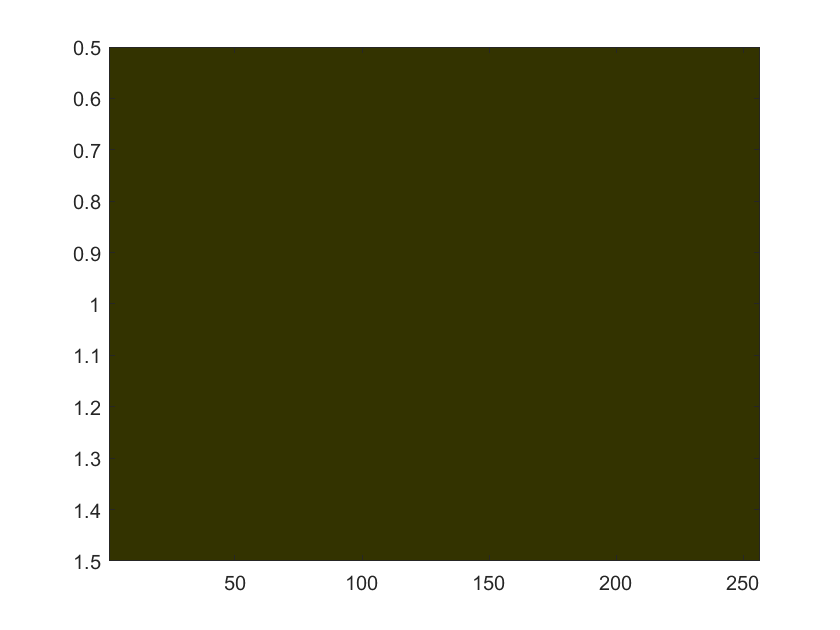

clc
ini=zeros(1,256);
n=input('Enter the number of nuclei : ');
t=input('Enter the number of steps for SRX : ');
m=input('Enter the number of steps for DRX : ');
inc_dd=input("Enter the increase in Dislocation Density : ");
nucl_dd=input("Enter the critical nucleation Dislocation Density : ");
crit_dd=input('Enter Critical Dislocation Density : ');
wt_max=input('Enter maximum waiting time : ');
prep=input('Enter the number of precipitates : ');
image(ini)
colormap("colorcube")

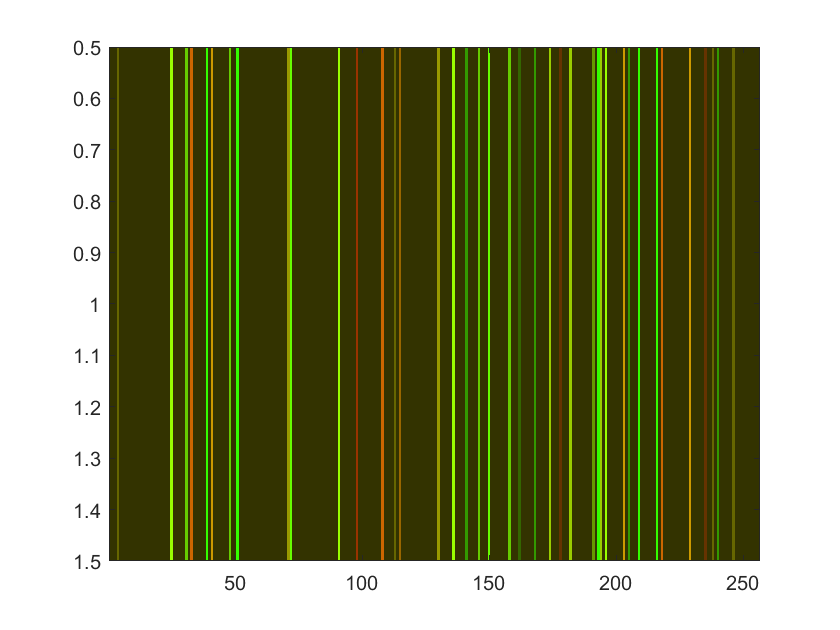

for i=1:n
    x=randi(256);
    ini(x)=randi(18);
end
image(ini)
colormap("colorcube")

ini_exp=[ini(256) ini ini(1)];
ini_exp3=ini_exp;
%SRX starts
for j=1:t
    ini_exp=ini_exp3;
    for i=2:257
        c1=0;
        St=0;
        if ini_exp(i)==0
            if randi(100)==1
                if ini_exp(i-1)~=0
                    c1=c1+1;
                    St(c1)=ini_exp(i-1);
                end
                if ini_exp(i+1)~=0
                    c1=c1+1;
                    St(c1)=ini_exp(i+1);
                end
                ini_exp3(i)=mode(St);
            end
        end
    end
end
ini_exp3(2:257)

ans =      7     7     7     7     7     7     7     7     7     7     1     1     1     1     1     1     1     1     1     1     1     1    15    15    15    15    15    15     9     9     9     9    17    17    17     5     5     5     5     5    18    18    18     9     9     9     9     9     5     5


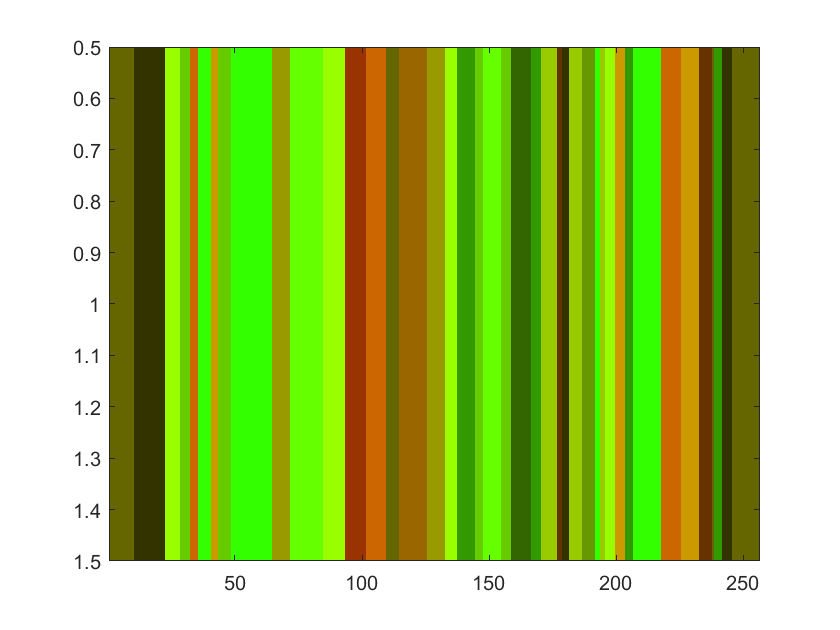

ini_exp=ini_exp3;
image(ini_exp(2:257))
colormap('colorcube')

%Counting Grains after SRX
count1=0;
for i=2:256
    if ini_exp(i)-ini_exp(i+1)~=0
        count1=count1+1;
    end
end

count1 =     41


room=0;
count5=0;
ind_st=0;
%Finding cells at GB
for i=3:255
    if abs(ini_exp(i)-ini_exp(i-1))>0
        count5=count5+1;
        ind_st(count5)=i;
    elseif abs(ini_exp(i)-ini_exp(i+1))>0
        count5=count5+1;
        ind_st(count5)=i;
    end 
end
count6=0;
%Introducing precipitates
for i=1:prep
    x=randi(count5);
    if ini_exp(ind_st(x))~=0 && ini_exp(ind_st(x)+1)~=0
        count6=count6+1;
        ini_exp(ind_st(x))=0;
        ini_exp(ind_st(x)+1)=0;
        room(count6)=ind_st(x);
    end
end

room =    145    95   178   139   227   126   194   148   188   110   172   219    29    24   234


ans =      7     7     7     7     7     7     7     7     7     7     1     1     1     1     1     1     1     1     1     1     1     1     0     0    15    15    15     0     0     9     9     9    17    17    17     5     5     5     5     5    18    18    18     9     9     9     9     9     5     5


count1=0;
for i=2:256
    if ini_exp(i)-ini_exp(i+1)~=0
        count1=count1+1;
    end
end
room1=zeros(1,count6);
for j=1:count6
    room1(j)=room(j)-1;
end
room2=[room room1];

room1 =    144    94   177   138   226   125   193   147   187   109   171   218    28    23   233


room2 =    145    95   178   139   227   126   194   148   188   110   172   219    29    24   234   144    94   177   138   226   125   193   147   187   109   171   218    28    23   233


disp('The actual number of precipitates are')

The actual number of precipitates are


count6

count6 =     15


%Randomly assigning waiting time
wt=zeros(1,256);
for i=1:256
    wt(i)=randi(wt_max);
end
wt=[wt(256) wt wt(1)];
wt1=wt;
%Randomly assigning dislocation densities
disl_den1=zeros(1,256);
for i=1:256
    disl_den1(i)=randi(5);
end
disl_den1=[disl_den1(256) disl_den1 disl_den1(1)];
count2=0;
ini_dummy=ini_exp(2:257);
ini_exp1=[ini_dummy(256) ini_dummy ini_dummy(1)];
ini_exp2=ini_exp1;
%DRX starts
for i=1:m
    ini_exp1=ini_exp2;
    ini_exp1=[ini_exp1(257) ini_exp1(2:257) ini_exp1(2)];
    disl_den=disl_den1;
    disl_den=[disl_den(257) disl_den(2:257) disl_den(2)];
    wt=[wt(257) wt(2:257) wt(2)];
    for j=setdiff([2:257],room2 + 1)
        count=0;
        store=0; 
        if abs(ini_exp1(j)-ini_exp1(j-1))>0 && ini_exp1(j-1)~=0
            count=count+1;
            store=abs(disl_den(j)-disl_den(j-1));
        end
        if abs(ini_exp1(j)-ini_exp1(j+1))>0 && ini_exp1(j+1)~=0
            count=count+1;
            store=abs(disl_den(j)-disl_den(j+1));
        end
        if count==0
            wt(j)=wt(j)-1;
            disl_den1(j)=disl_den1(j)+inc_dd;
        end
        [max1,max_in]=max(store);
        if max1>=crit_dd
            if max_in==1
                if wt(j)==0
                    if randi(2)==1
                        disl_den1(j)=disl_den(j-1);
                        wt(j)=wt_max;
                        ini_exp2(j)=ini_exp1(j-1);
                    else
                        wt(j)=wt(j)-1;
                        disl_den1(j)=disl_den1(j)+inc_dd;
                        if abs(ini_exp1(j)-ini_exp1(j-1))>0 || abs(ini_exp1(j)-ini_exp1(j+1))>0
                            if disl_den(j)>=nucl_dd
                                if randi(1000)==1
                                    ini_exp2(j)=randi(18);
                                    disl_den1(j)=0;
                                    wt(j)=wt_max;
                                end
                            end
                        end
                    end
                else
                  wt(j)=wt(j)-1;
                  disl_den1(j)=disl_den1(j)+inc_dd;  
                  if abs(ini_exp1(j)-ini_exp1(j-1))>0 || abs(ini_exp1(j)-ini_exp1(j+1))>0
                      if disl_den(j)>=nucl_dd
                          if randi(1000)==1
                              ini_exp2(j)=randi(18);
                              disl_den1(j)=0;
                              wt(j)=wt_max;
                          end
                      end
                  end
                end
            elseif max_in==2
                if wt(j)==0
                    if randi(2)==1
                        disl_den1(j)=disl_den(j+1);
                        wt(j)=wt_max;
                        ini_exp2(j)=ini_exp1(j+1);
                    else
                        wt(j)=wt(j)-1;
                        disl_den1(j)=disl_den1(j)+inc_dd;
                        if abs(ini_exp1(j)-ini_exp1(j-1))>0 || abs(ini_exp1(j)-ini_exp1(j+1))>0
                            if disl_den(j)>=nucl_dd
                                if randi(1000)==1
                                    ini_exp2(j)=randi(18);
                                    disl_den1(j)=0;
                                    wt(j)=wt_max;
                                end
                            end
                        end
                    end
                else
                    wt(j)=wt(j)-1;
                    disl_den1(j)=disl_den1(j)+inc_dd;
                    if abs(ini_exp1(j)-ini_exp1(j-1))>0 || abs(ini_exp1(j)-ini_exp1(j+1))>0
                        if disl_den(j)>=nucl_dd
                            if randi(1000)==1
                                ini_exp2(j)=randi(18);
                                disl_den1(j)=0;
                                wt(j)=wt_max;
                            end
                        end
                    end
                end
            end
        else
          wt(j)=wt(j)-1;
          disl_den1(j)=disl_den1(j)+inc_dd;  
          if abs(ini_exp1(j)-ini_exp1(j-1))>0 || abs(ini_exp1(j)-ini_exp1(j+1))>0
              if disl_den(j)>=nucl_dd
                  if randi(1000)==1
                      ini_exp2(j)=randi(18);
                      disl_den1(j)=0;
                      wt(j)=wt_max; 
                  end
              end
          end
        end
    end
    count1=0;
    %counting grains
    for k=2:256
        if ini_exp2(k)-ini_exp2(k+1)~=0
            count1=count1+1;
        end
    end
    count2(i)=count1+1-count6;
end
%After DRX
ini_exp2(2:257)

ans =      7     7     7     7     7     7     7     2     2     7     6     6     6     4     4     2     8     8     3     1     1    12     0     0    10    10     8     0     0     8     1    15     7    16     7     3     3    13    13    13    13    13    13    10     6     8     8     8     8    13


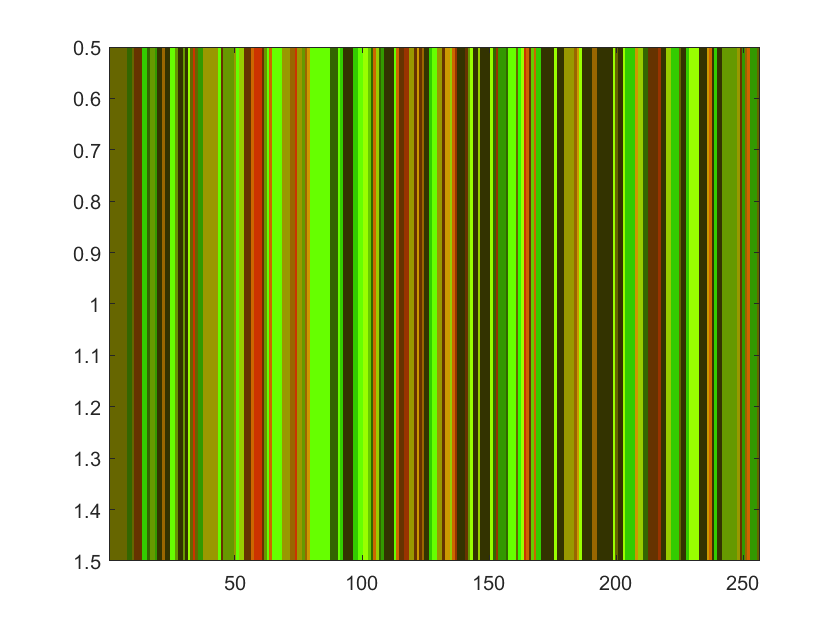

image(ini_exp2(2:257))
colormap('colorcube')

%plotting number of grains data

count2 =     41    41    41    41    41    41    41    42    42    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    43    44    44    44    44    44    44    44    44    44    45    45    45    45    45    45


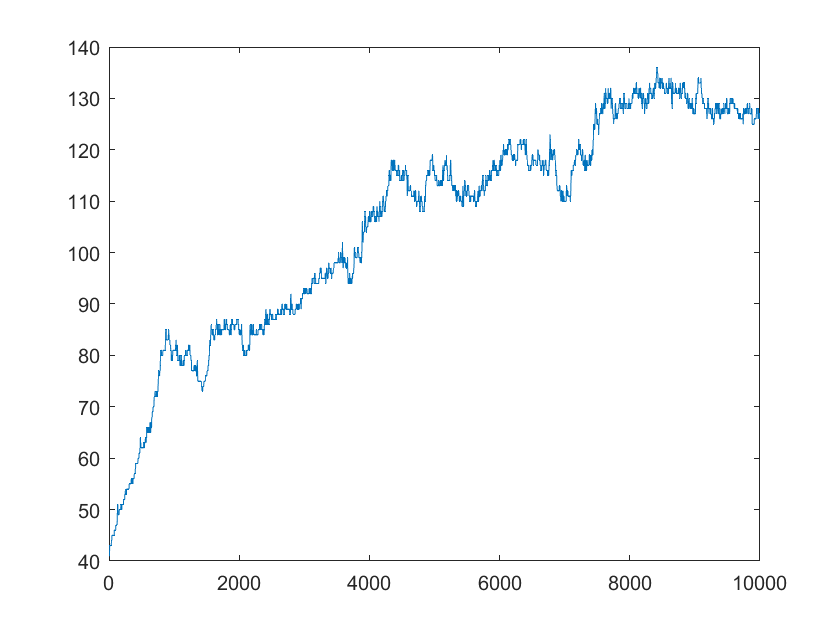

plot([1:m],count2)